Extracted 52 features from 635 samples
Training set: 240 Non-Seizure samples, 205 Seizure samples
Validation set: 51 Non-Seizure samples, 44 Seizure samples
Test set: 55 Non-Seizure samples, 40 Seizure samples
Features standardized using training data statistics
Class ratio (Non-Seizure:Seizure): 1.1707:1
Random Forest model training completed
Number of trees: 1000
Optimal decision threshold: 0.44407
Validation Accuracy: 80.00%
Validation Sensitivity: 81.82%
Validation Specificity: 78.43%


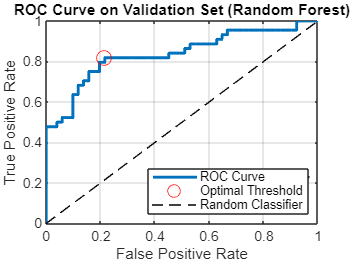

Test Accuracy: 74.74%
Sensitivity (Seizure Recall): 85.00%
Specificity: 67.27%
Precision: 65.38%
F1 Score: 73.91


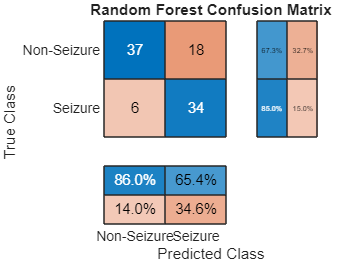

Unrecognized function or variable 'oobError'.

Error in untitled>analyzeFeatureImportance (line 245)
    oobError = oobError(rfModel); % Baseline OOB error

Error in untitled>main_seizure_detection (line 28)
    analyzeFeatureImportance(rfModel, XTest, YTest, entries);

main_seizure_detection(outputEntries);

function main_seizure_detection(entries)
    % Set random seed for reproducibility
    rng(42);
    
    % Extract and prepare data
    [X, labels] = extractFeatures(entries);
    
    % Split data into train, validation, and test sets
    [XTrain, YTrain, XVal, YVal, XTest, YTest] = splitData(X, labels);
    
    % Standardize features
    [XTrain, XVal, XTest] = standardizeFeatures(XTrain, XVal, XTest);
    
    % Train Random Forest model with class weights
    rfModel = trainWeightedRandomForest(XTrain, YTrain);
    
    % Optimize decision threshold using validation set
    [optThreshold, fpr, tpr, thresholds] = optimizeThreshold(rfModel, XVal, YVal);
    
    % Plot ROC curve
    plotROC(fpr, tpr, thresholds, optThreshold);
    
    % Evaluate on test set
    evaluateModel(rfModel, XTest, YTest, optThreshold);
    
    % Analyze feature importance
    analyzeFeatureImportance(rfModel, XTest, YTest, entries);
end

%% Extract features from the data structure
function [X, labels] = extractFeatures(entries)
    % Initialize
    numEntries = length(entries);
    featureList = fieldnames(entries{1}.alphaRQA);  % Assumes all RQA structs have same fields
    numFeaturesPerBand = numel(featureList);
    numBands = 4;  % alpha, beta, delta, theta
    totalFeatures = numFeaturesPerBand * numBands;
    
    % Allocate space
    X = zeros(numEntries, totalFeatures);
    labels = zeros(numEntries, 1);
    
    % Extract features
    for i = 1:numEntries
        featVec = [];
        for band = {'alphaRQA', 'betaRQA', 'deltaRQA', 'thetaRQA'}
            bandStruct = entries{i}.(band{1});
            bandFeatures = cellfun(@(f) bandStruct.(f), featureList)';  % transpose to row
            featVec = [featVec, bandFeatures];  % 1x13 per band
        end
        X(i, :) = featVec;  % now 1x52
        labels(i) = entries{i}.seizure;
    end
    
    % Confirm numeric matrix
    assert(isnumeric(X), 'Feature matrix X is not numeric!');
    
    % Convert labels to categorical
    labels = categorical(labels, [0 1], {'Non-Seizure', 'Seizure'});
    
    disp(['Extracted ' num2str(totalFeatures) ' features from ' num2str(numEntries) ' samples']);
end

%% Split data into train, validation, and test sets
function [XTrain, YTrain, XVal, YVal, XTest, YTest] = splitData(X, labels)
    % Shuffle and split into train (70%), val (15%), test (15%)
    numSamples = size(X, 1);
    idx = randperm(numSamples);
    trainIdx = idx(1:round(0.7 * numSamples));
    valIdx   = idx(round(0.7 * numSamples) + 1 : round(0.85 * numSamples));
    testIdx  = idx(round(0.85 * numSamples) + 1 : end);

    XTrain = X(trainIdx, :);
    YTrain = labels(trainIdx);
    XVal = X(valIdx, :);
    YVal = labels(valIdx);
    XTest = X(testIdx, :);
    YTest = labels(testIdx);
    
    % Display class distribution in training set
    numNonSeizure = sum(YTrain == 'Non-Seizure');
    numSeizure = sum(YTrain == 'Seizure');
    disp(['Training set: ' num2str(numNonSeizure) ' Non-Seizure samples, ' ...
          num2str(numSeizure) ' Seizure samples']);
    
    % Display class distribution in validation set
    disp(['Validation set: ' num2str(sum(YVal == 'Non-Seizure')) ' Non-Seizure samples, ' ...
          num2str(sum(YVal == 'Seizure')) ' Seizure samples']);
    
    % Display class distribution in test set
    disp(['Test set: ' num2str(sum(YTest == 'Non-Seizure')) ' Non-Seizure samples, ' ...
          num2str(sum(YTest == 'Seizure')) ' Seizure samples']);
end

%% Standardize features
function [XTrain, XVal, XTest] = standardizeFeatures(XTrain, XVal, XTest)
    % Standardize features using training data statistics
    [XTrain, mu, sigma] = zscore(XTrain);
    
    % Apply same transformation to validation and test sets
    XVal = (XVal - mu) ./ sigma;
    XTest = (XTest - mu) ./ sigma;
    
    % Replace NaN or Inf values with 0
    XTrain(isnan(XTrain) | isinf(XTrain)) = 0;
    XVal(isnan(XVal) | isinf(XVal)) = 0;
    XTest(isnan(XTest) | isinf(XTest)) = 0;
    
    disp('Features standardized using training data statistics');
end

%% Train Random Forest model with class weights
function rfModel = trainWeightedRandomForest(XTrain, YTrain)
    % Count samples in each class
    numNonSeizure = sum(YTrain == 'Non-Seizure');
    numSeizure = sum(YTrain == 'Seizure');
    
    % Calculate class weights (inverse frequency)
    classRatio = numNonSeizure / numSeizure;
    disp(['Class ratio (Non-Seizure:Seizure): ' num2str(classRatio) ':1']);
    
    % Define class weights: higher weight for minority class (Seizure)
    classWeights = struct('Non_Seizure', 1, 'Seizure', classRatio);
    
    % Train Random Forest using TreeBagger
    rfModel = TreeBagger(1000, XTrain, YTrain, ...
        'Method', 'classification', ...
        'NumPredictorsToSample', sqrt(52), ... % Use sqrt(numFeatures) for each split
        'MinLeafSize', 5, ... % Minimum leaf size to prevent overfitting
        'ClassNames', {'Non-Seizure', 'Seizure'}, ...
        'Cost', [0 1; classRatio 0]); % Cost matrix similar to SVM
    
    % Display training completion
    disp('Random Forest model training completed');
    disp(['Number of trees: ' num2str(rfModel.NumTrees)]);
end

%% Optimize decision threshold using validation set
function [optThreshold, fpr, tpr, thresholds] = optimizeThreshold(rfModel, XVal, YVal)
    % Predict probabilities on validation set
    [~, YValScores] = predict(rfModel, XVal); % Second column is probability for 'Seizure'
    seizureProbs = YValScores(:, 2);
    
    % Create ROC curve on validation set
    [fpr, tpr, thresholds] = perfcurve(YVal, seizureProbs, 'Seizure');
    
    % Find optimal threshold (closest to perfect corner: 0 FPR, 1 TPR)
    distToIdeal = sqrt((fpr - 0).^2 + (tpr - 1).^2);
    [~, idxOptThresh] = min(distToIdeal);
    optThreshold = thresholds(idxOptThresh);
    
    disp(['Optimal decision threshold: ' num2str(optThreshold)]);
    
    % Calculate validation metrics at optimal threshold
    YValPredOpt = categorical(seizureProbs >= optThreshold, [0 1], {'Non-Seizure', 'Seizure'});
    valAccuracy = sum(YValPredOpt == YVal) / numel(YVal);
    
    % Detailed metrics
    TP = sum(YValPredOpt == 'Seizure' & YVal == 'Seizure');
    FP = sum(YValPredOpt == 'Seizure' & YVal == 'Non-Seizure');
    TN = sum(YValPredOpt == 'Non-Seizure' & YVal == 'Non-Seizure');
    FN = sum(YValPredOpt == 'Non-Seizure' & YVal == 'Seizure');
    
    valSensitivity = TP / (TP + FN) * 100;
    valSpecificity = TN / (TN + FP) * 100;
    
    disp(['Validation Accuracy: ' num2str(valAccuracy * 100, '%.2f') '%']);
    disp(['Validation Sensitivity: ' num2str(valSensitivity, '%.2f') '%']);
    disp(['Validation Specificity: ' num2str(valSpecificity, '%.2f') '%']);
end

%% Plot ROC curve
function plotROC(fpr, tpr, thresholds, optThreshold)
    % Find index of optimal threshold
    [~, idxOptThresh] = min(abs(thresholds - optThreshold));
    
    % Plot ROC curve
    figure;
    plot(fpr, tpr, 'LineWidth', 2);
    hold on;
    plot(fpr(idxOptThresh), tpr(idxOptThresh), 'ro', 'MarkerSize', 10);
    plot([0 1], [0 1], 'k--');
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title('ROC Curve on Validation Set (Random Forest)');
    legend('ROC Curve', 'Optimal Threshold', 'Random Classifier', 'Location', 'southeast');
    grid on;
    
    % Add AUC value to the plot
    AUC = trapz(fpr, tpr);
    text(0.6, 0.2, ['AUC = ' num2str(AUC, '%.3f')], 'FontSize', 12);
end

%% Evaluate model on test set
function evaluateModel(rfModel, XTest, YTest, optThreshold)
    % Predict probabilities on test set
    [~, YTestScores] = predict(rfModel, XTest);
    seizureProbs = YTestScores(:, 2);
    YTestPred = categorical(seizureProbs >= optThreshold, [0 1], {'Non-Seizure', 'Seizure'});
    
    % Evaluate accuracy
    testAccuracy = sum(YTestPred == YTest) / numel(YTest);
    disp(['Test Accuracy: ' num2str(testAccuracy * 100, '%.2f') '%']);
    
    % Calculate detailed metrics
    TP = sum(YTestPred == 'Seizure' & YTest == 'Seizure');
    FP = sum(YTestPred == 'Seizure' & YTest == 'Non-Seizure');
    TN = sum(YTestPred == 'Non-Seizure' & YTest == 'Non-Seizure');
    FN = sum(YTestPred == 'Non-Seizure' & YTest == 'Seizure');
    
    sensitivity = TP / (TP + FN) * 100; % Recall for seizure class
    specificity = TN / (TN + FP) * 100;
    precision = TP / (TP + FP) * 100;
    f1score = 2 * (precision * sensitivity) / (precision + sensitivity);
    
    disp(['Sensitivity (Seizure Recall): ' num2str(sensitivity, '%.2f') '%']);
    disp(['Specificity: ' num2str(specificity, '%.2f') '%']);
    disp(['Precision: ' num2str(precision, '%.2f') '%']);
    disp(['F1 Score: ' num2str(f1score, '%.2f')]);
    
    % Show confusion matrix
    figure;
    cm = confusionchart(YTest, YTestPred);
    cm.Title = 'Random Forest Confusion Matrix';
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
end

%% Analyze feature importance
function analyzeFeatureImportance(rfModel, XTest, YTest, entries)
    % Get feature list for naming
    featureList = fieldnames(entries{1}.alphaRQA);
    bands = {'alpha', 'beta', 'delta', 'theta'};
    allFeatureNames = {};
    featureIdx = 1;
    for b = 1:length(bands)
        for f = 1:length(featureList)
            allFeatureNames{featureIdx} = [bands{b} '_' featureList{f}];
            featureIdx = featureIdx + 1;
        end
    end
    
    % Use out-of-bag feature importance from Random Forest
    oobError = oobError(rfModel); % Baseline OOB error
    totalFeatures = size(XTest, 2);
    featureImportance = zeros(totalFeatures, 1);
    
    disp('Calculating feature importance via out-of-bag permutation...');
    fprintf('Progress: ');
    progressMarks = 10;
    progressStep = totalFeatures / progressMarks;
    
    % Permute each feature and measure OOB error increase
    for i = 1:totalFeatures
        permutedModel = rfModel;
        permutedXTrain = rfModel.X;
        permutedXTrain(:, i) = permutedXTrain(randperm(size(permutedXTrain, 1)), i);
        permutedModel.X = permutedXTrain; % Update training data with permuted feature
        permutedOOBError = oobError(permutedModel);
        featureImportance(i) = permutedOOBError - oobError; % Increase in error
        
        % Show progress
        if mod(i, round(progressStep)) == 0
            fprintf('.');
        end
    end
    fprintf('\n');
    
    % Get top 10 features
    [sortedImportance, sortedIndices] = sort(featureImportance, 'descend');
    topFeatures = sortedIndices(1:min(10, length(sortedIndices)));
    
    % Plot top features
    figure;
    bar(sortedImportance(1:10));
    xlabel('Feature Rank');
    ylabel('Importance Score (OOB Error Increase)');
    title('Top 10 Most Important Features (Random Forest)');
    xticks(1:10);
    xticklabels(allFeatureNames(sortedIndices(1:10)));
    xtickangle(45);
    
    % Display top 5 features with their importance scores
    disp('Top 5 most important features:');
    for i = 1:5
        disp([num2str(i) '. ' allFeatureNames{sortedIndices(i)} ': ' ...
            num2str(sortedImportance(i), '%.4f')]);
    end
end